Q = [16, 4];
flow = 15;
fhigh = 120;
T = 8;
fs = 250;
N = AudioDataConverter.L/4;
scat = Scattering(Q, T, fs, N, flow, fhigh, 1);
figure
P = sum(abs(scat.filterBanks(1).Psi).^2, 1);
2/max(P)

ans =

    0.1951



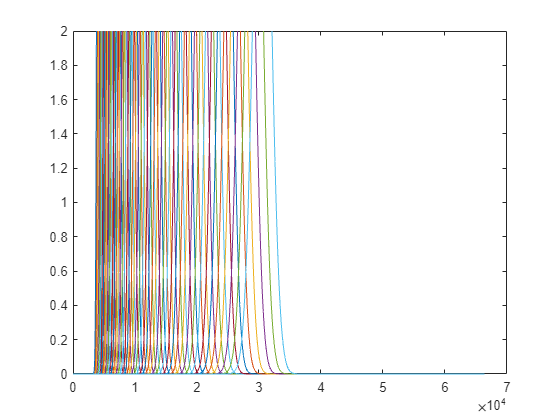

plot(abs(scat.filterBanks(1).Psi).^2')
ylim([0, 2])

sum(abs(scat.filterBanks(1).psi).^2, 2)

ans =     0.0266
    0.0278
    0.0290
    0.0303
    0.0316
    0.0330
    0.0345
    0.0360
    0.0376
    0.0393


scat.filterBanks(1).lambdas'

ans =    94.2478
   98.4205
  102.7779
  107.3283
  112.0801
  117.0423
  122.2242
  127.6356
  133.2865
  139.1876


scat.filterBanks(1).fc

ans =    15.0000   15.6641   16.3576   17.0818   17.8381   18.6279   19.4526   20.3138   21.2132   22.1524   23.1332   24.1574   25.2269   26.3438   27.5101   28.7281   30.0000   31.3282   32.7152   34.1637   35.6762   37.2557   38.9052   40.6277   42.4264   44.3048   46.2663   48.3147   50.4538   52.6876   55.0202   57.4562   60.0000   62.6564   65.4305   68.3273   71.3524   74.5115   77.8104   81.2553   84.8528   88.6096   92.5326   96.6294  100.9076  105.3751  110.0405  114.9124


max(scat.filterBanks(2).psiBWHz)

ans = 1.6818

scat.filterBanks(1).getSSamplingFreq()

ans = 0.5040

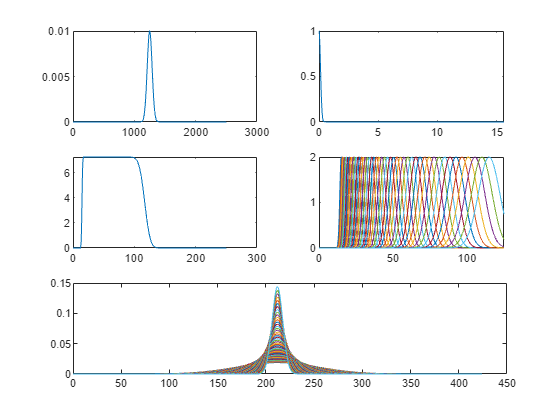

figure
scat.filterBanks(1).plot()

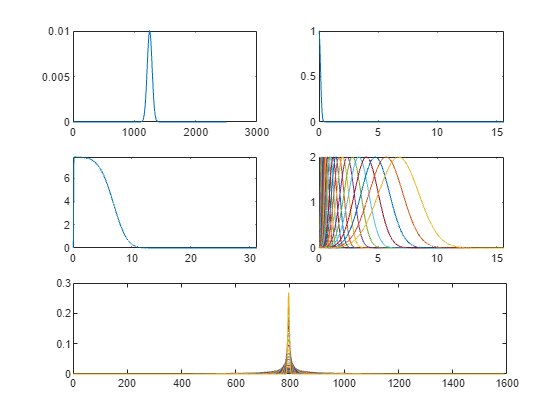

figure
scat.filterBanks(2).plot()

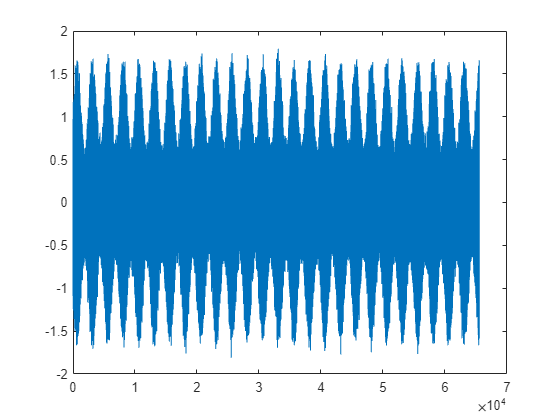

t = (0:N-1)/fs;
t = t';
x = randn(N, 1)*0.1;
f0 = 60.*(t < 100) + 30.*(t > 100) + 45*sin(2*pi*0.05*t).*(t < 50) + 5*sin(2*pi*0.8*t).*(t > 150 & t < 200) + 5*sin(2*pi*1.5*t).*(t > 200) + 2*sin(2*pi*1*t).*(t < 100 & t > 50);
f0 = cumsum(f0/fs);
y = sin(2*pi*f0) .* (1 + 0.5*sin(2 * pi * t * 0.1));
% x = x + bandpass(randn(N, 1)*4 .* (t < 180 & t > 170), [25, 80], fs);

figure
plot(x+y);

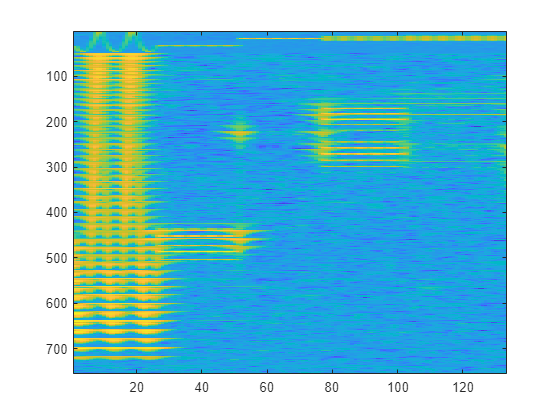

coeffs = scat.scattering(x+y);
figure
imagesc(log(coeffs./prctile(coeffs, 20, 2)))

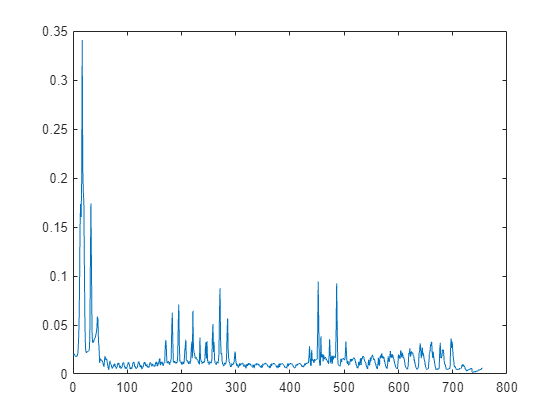

% set(gca, "YDir", "normal")
figure
plot(mean(coeffs, 2))

N = 200000;
w = randn(N,1);
scat = Scattering(10, 1, 1000, N, 50, 250);

Not enough input arguments.

Error in Scattering (line 12)
            obj.filterBanks(1) = SFB(Q(1), T, fs, N, flow, fhigh, true, oversample);

scat.filterBanks(1).plot()
coeffs = scat.scattering(w);
mean(coeffs.^2, 2)./(scat.filterBanks(1).lambdas')

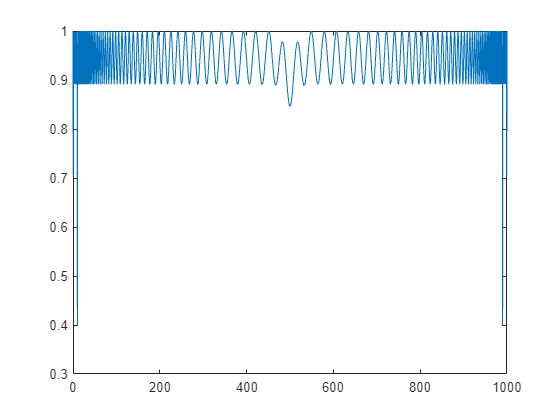

sf = waveletScattering('QualityFactors',Q,...
    'SamplingFrequency',fs, 'SignalLength', N, 'InvarianceScale',2, 'OptimizePath',false);
[lpsum,f] = littlewoodPaleySum(sf);
plot(f,lpsum(:,1))

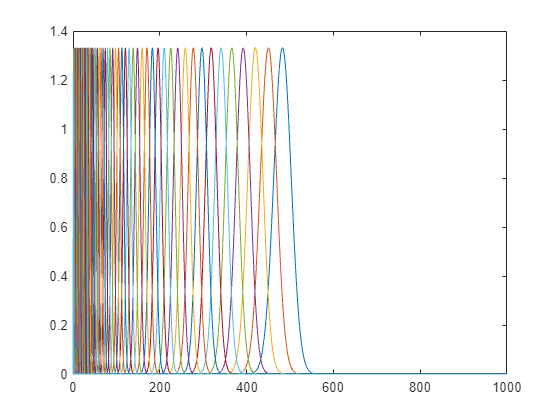

[filters,f] = filterbank(sf);
figure
plot(f,filters{2}.psift)

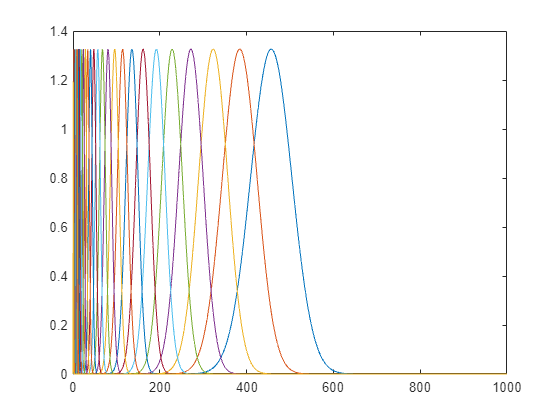

figure
plot(f,filters{3}.psift)

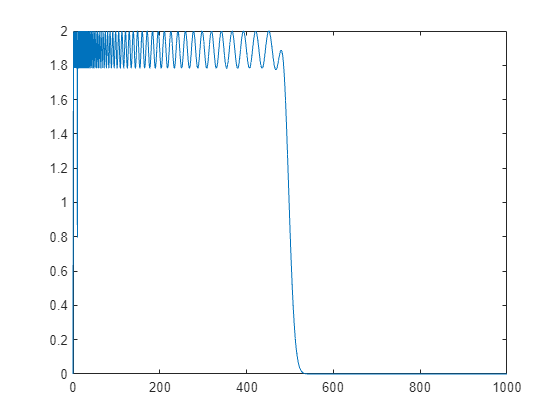

plot(f,sum(filters{2}.psift.^2, 2))

max(sum(filters{2}.psift, 2))/max(P)

ans =

    0.3885



[M, u] = featureMatrix(sf, single(x));
% [s, u] = scatteringTransform(sf,x)